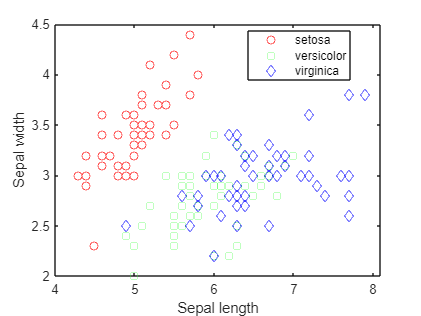

load fisheriris.mat
X = meas(:,1:2);
Y = species;
labels = unique(Y);


figure;
gscatter(X(:,1), X(:,2), species,'rgb','osd');
xlabel('Sepal length');
ylabel('Sepal width'); 


myrnd = randperm(150);
num_training = round(150*0.8);

Xtrain= X(myrnd(1:num_training),:);
Ytrain = Y(myrnd(1:num_training));
Xtest = X(myrnd(num_training+1:end),:);
Ytest = Y(myrnd(num_training+1:end));

mdl = fitcnb(Xtrain,Ytrain);

[predictedspecies,Posterior,~] = predict(mdl,Xtest);

index = cellfun(@strcmp, predictedspecies, Ytest);
Acc  = sum(index)/(150-num_training);
disp(['The accuracy is: ',num2str(Acc*100), '%.'])

The accuracy is: 83.3333%.


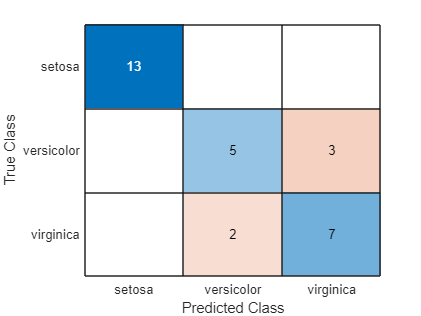


confusionchart(Ytest,predictedspecies)


str = convertCharsToStrings(Ytest);
str = categorical(str);
categories(str)

ans = 3×1 cell array
    {'setosa'    }
    {'versicolor'}
    {'virginica' }


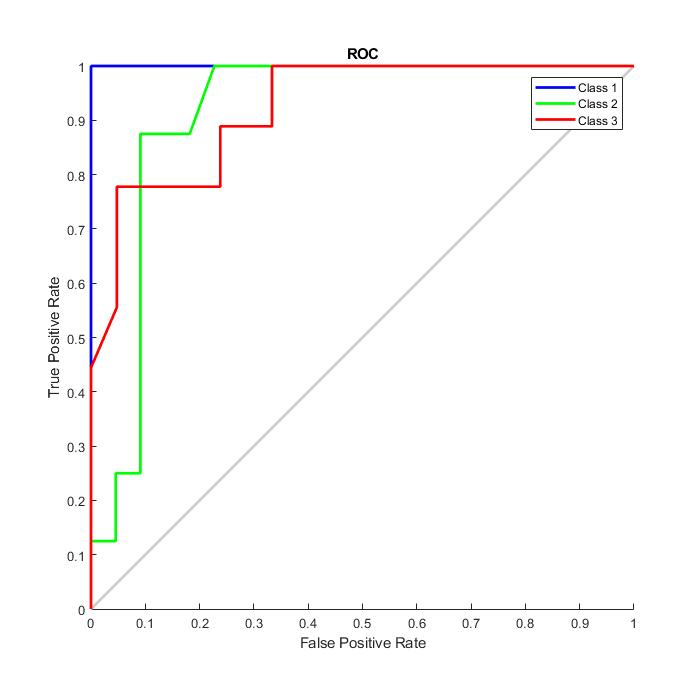


onehotLabels = onehotencode(str,2);
plotroc(onehotLabels',Posterior')